# STI for TS images (less memory)

Script to calculate STI for time series images. Optimised for smaller memory.

## Inputs & arguments

- **time series images**: The images at different dates and years (say n images).

- mask: Mask file for each year.

- **spatilal lag**: The number of pixels to expand from centroid.

## outputs:

- **STI series images**: The STI index at each pixel and date (return n-1 images).

Code:

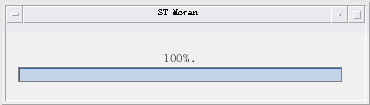

% Choose mask file.
[File, Path]=uigetfile({'*.tif'},'Choose mask file.','Multiselect','off','/home/dk/文档/Tutor/localSTMoran/其他数据与资料/');
[mask, R0] = geotiffread(strcat(Path, File));
[x,y] = size(mask);

% Choose harmonic models.
[fileH, pathH] = uigetfile({'*.tif'}, 'Choose harmonic params imagery.', 'Multiselect', 'on', '/home/dk/文档/Tutor/localSTMoran/其他数据与资料/');
[~, fileLengthH] = size(fileH);
paramsH = zeros(x,y,fileLengthH);
for num = 1:fileLengthH
    paramsH(:,:,num) = geotiffread(strcat(pathH, char(fileH(num))));
end

% Read Params.
    beta0 = paramsH(:,:,1);
    beta1 = paramsH(:,:,2);
    beta2 = paramsH(:,:,3);
    beta3 = paramsH(:,:,4);

    
% Choose time series imagery.
[file, path] = uigetfile({'*.tif'}, 'Choose imagery.', 'Multiselect', 'on', '/home/dk/文档/Tutor/localSTMoran/(第二次挑选）衡阳盆地Landsat一致性数据生成结果/image/');
[~, fileLength] = size(file);

dates= zeros(1,2);
ndvi = nan(x,y,2);
residual = nan(x,y,2);

% Timer and waitbar.
tic
wb = waitbar(0, 'Starting...');
set(wb,'Name','ST Moran');

% Read & mask time series images and batch NDVI.
for num = 2:fileLength
    for i = num-1:num   % Batch NDVI
        idx = i-num+2;  % index start from 1.
        [temp, ~] = geotiffread(strcat(path,char(file(i))));
        
        % Local variables.
        NIR = double(temp(:,:,4));
        R = double(temp(:,:,3));
        ndvi = (NIR - R) ./ (NIR + R);
        ndvi(ndvi>=1) = 1;
        ndvi(ndvi<=-1) = -1;
        ndvi(mask ~=1) = nan;
        
        % Harmonic modeling and getting residual
        DOYtemp = char(file(i));
        DOY = str2double(DOYtemp(7:end-4));
        angle = 2 * pi * DOY / 365;
        harmonic = beta0 + beta1 .* DOY + beta2 * cos(angle) + beta3 * sin(angle);
        harmonic(mask ~= 1) = nan;
        residual(:,:,idx) = ndvi - harmonic;
    end
    residual(~isfinite(residual)) = nan;
    
    % ST Moran's I
    lags = 1;
    lagt = 1;
    im1 = residual(:,:,1);
    im2 = residual(:,:,2);
    STI = STMoran(im1, mask, im2, mask, lags, lagt);
    waitbar(double(num-1)/(fileLength-1),wb,strcat(num2str(double(num-1)/(fileLength-1) * 100),'%.'));
    outName = strcat(path,'result/STI_',DOYtemp(7:end-4));
    geotiffwrite(outName,STI,R0,'CoordRefSysCode',32649);
end

toc

时间已过 10168.656148 秒。
